## Parámetros

rotacion = pi/4; %pi/4
factor = 4/3; %1 a 4/3
lmin = 15;
es = 3.5;
hojas = 4;
n = 3000;

lcx = 20;
lcy = 9;

q10 = 170*(pi/180);
q20 = -160*(pi/180);

%Valores iniciales de los angulos
q10i = q10;
q20i = q20;

l1 = 19;
l2 = 18;

## Trébol estilizado

[r,theta]=trayectoria0(rotacion,lmin, factor,es,hojas,n);

xp = r.*cos(theta);
yp = r.*sin(theta);
plot(xp,yp)
title('Trébol estilizado')
a = ((lmin/2)*factor)*(1+sin(rotacion));
xlim ([-a a])
ylim ([-a a])

## Trasladando al origen

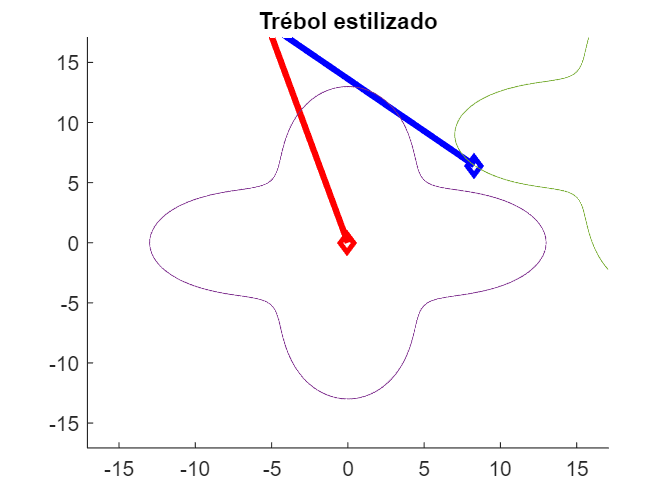

[x,y]=Totrigen(lcx,lcy,theta,r);
plot(x,y)

## Cinemática inversa

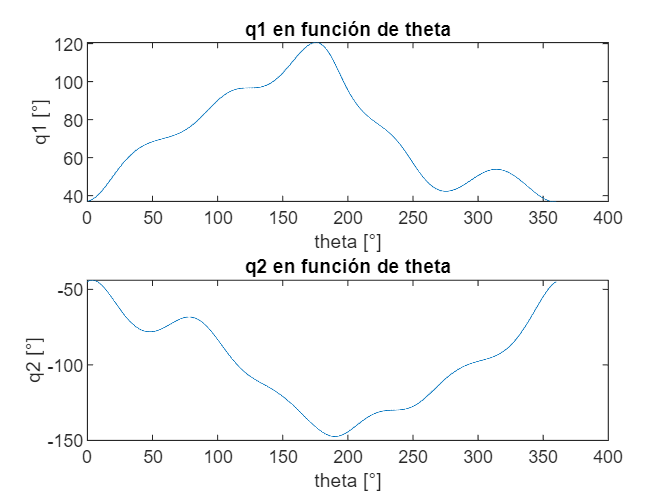

q1 = zeros(length(x),1);
q2 = zeros(length(x),1);
for i = 1:length(x)
    [q1(i), q2(i)] = Cinversa(l1,l2,x(i),y(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
end

figure()
subplot(2,1,1);
plot((theta)*(180/pi),q1*(180/pi))
title('q1 en función de theta')
ylabel('q1 [°]')
xlabel('theta [°]')

subplot(2,1,2); 
plot(theta*(180/pi),q2*(180/pi))
title('q2 en función de theta')
ylabel('q2 [°]')
xlabel('theta [°]')

## Trayectoria de acercamiento

[x20, y20] = Cdirecta(l1,l2,q10i,q20i); %Posición inicial extremo distal
[distPoint] = sqrt((x-x20).^2+(y-y20).^2);
minimo = min(distPoint)

minimo = 8.2943

pos = find(distPoint==minimo,1)

pos = 1525

distPoint(pos);
%pos = (n/2) + 1; %Aprox en pi
[x2f, y2f] = Totrigen(lcx,lcy,theta(pos),r(pos));
Xaprox = linspace(x20,x2f,100);
Yaprox = linspace(y20,y2f,100);
% figure()
% hold on
% plot(Xaprox,Yaprox)
% plot(x,y)
% hold off

## Perfil trapezoidal Acercamiento

deltaX = x2f-x20

deltaX = 8.0710

deltaY = y2f-y20

deltaY = 1.9116

t = 5; %s
t1 = t/3; %Perfiles con tiempos iguales
VcX = (0.5*deltaX)/t1;
VcY = (0.5*deltaY)/t1;

t = linspace(0,t,100);

Vx = VcX*t-VcX*(t-t1).*(t>=t1)-VcX*(t-2*t1).*(t>=2*t1)

Vx =          0    0.1223    0.2446    0.3669    0.4891    0.6114    0.7337    0.8560    0.9783    1.1006    1.2229    1.3452    1.4674    1.5897    1.7120    1.8343    1.9566    2.0789    2.2012    2.3235    2.4457    2.5680    2.6903    2.8126    2.9349    3.0572    3.1795    3.3018    3.4240    3.5463    3.6686    3.7909    3.9132    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355    4.0355


Vy = VcY*t-VcY*(t-t1).*(t>=t1)-VcY*(t-2*t1).*(t>=2*t1)

Vy =          0    0.0290    0.0579    0.0869    0.1159    0.1448    0.1738    0.2027    0.2317    0.2607    0.2896    0.3186    0.3476    0.3765    0.4055    0.4344    0.4634    0.4924    0.5213    0.5503    0.5793    0.6082    0.6372    0.6662    0.6951    0.7241    0.7530    0.7820    0.8110    0.8399    0.8689    0.8979    0.9268    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558    0.9558




Px = 0.5*VcX*t.^2-0.5*VcX*((t-t1).^2).*(t>=t1)-0.5*VcX*((t-2*t1).^2).*(t>=2*t1)+x20

Px =    -0.9848   -0.9817   -0.9725   -0.9570   -0.9354   -0.9076   -0.8736   -0.8335   -0.7872   -0.7347   -0.6760   -0.6112   -0.5401   -0.4629   -0.3795   -0.2900   -0.1943   -0.0924    0.0157    0.1300    0.2504    0.3770    0.5098    0.6488    0.7939    0.9452    1.1027    1.2664    1.4362    1.6123    1.7945    1.9828    2.1774    2.3781    2.5819    2.7857    2.9895    3.1933    3.3972    3.6010    3.8048    4.0086    4.2124    4.4162    4.6200    4.8238    5.0277    5.2315    5.4353    5.6391


c1 = 0.5*VcX*t1^2-VcX*t1

c1 = -0.6726

b = 3*VcX*t1;
c2 = 2*VcX*t1+c1+0.5*VcX*t1^2-b*t1

c2 = -9.4161

%Px = (0.5*VcX*t.^2).*(t<=t1)+(VcX*t+c1).*(t>t1&t<=2*t1)+(-0.5*VcX*t.^2+b*t+c2).*(t>2*t1&t<=3*t1)
Px(end)

ans = 12.4668

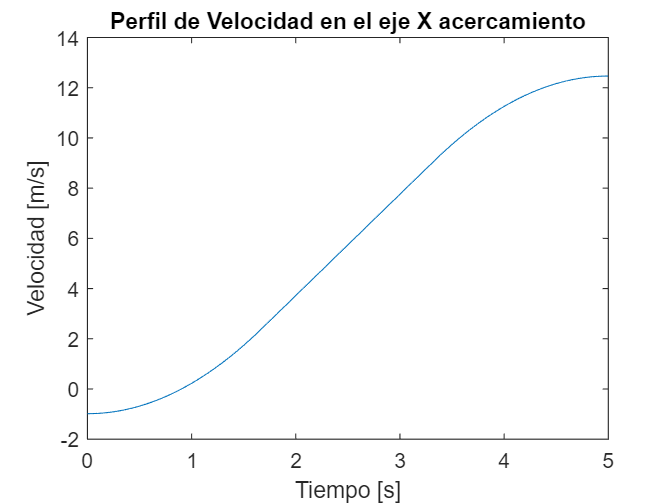


figure()
plot(t,Vx)
xlabel('Tiempo [s]')
ylabel('Velocidad [m/s]')
title('Perfil de Velocidad en el eje X acercamiento')

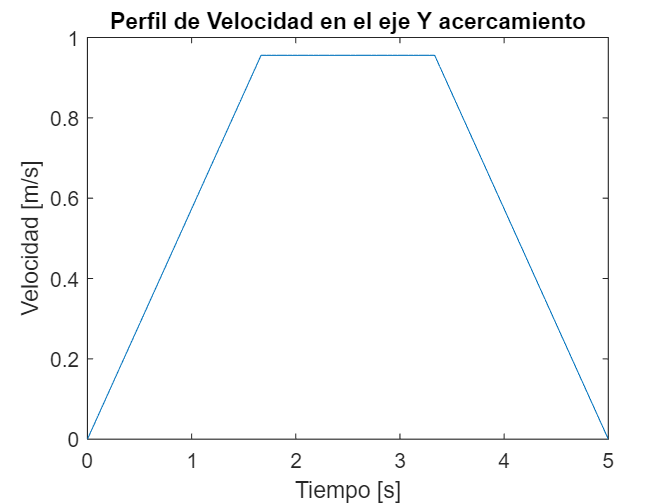


figure()
plot(t,Vy)
xlabel('Tiempo [s]')
ylabel('Velocidad [m/s]')
title('Perfil de Velocidad en el eje Y acercamiento')

## Visualización

%Vectores de la posición distal del mecanismo en todo momento
XTotal = [Xaprox, x(1,pos:end), x(1,1:pos-1)];
YTotal = [Yaprox, y(1,pos:end), y(1,1:pos-1)];

%Cinematica inversa de todo el movimiento
q1 = zeros(1,length(XTotal));
q2 = zeros(1,length(YTotal));
figure(); %creamos la figura para visualizar
for i = 1:length(x)
    %Cinematica inversa
    [q1(i), q2(i)] = Cinversa(l1,l2,XTotal(i),YTotal(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
    %Gráfica
    cla;    %clear axes
    hold on
    plot(x,y);%Trebol base
    %Primer eslabon
    x1 = l1*cos(q1(i));
    y1 = l1*sin(q1(i));
    %Segundo eslabon
    x2 = XTotal(i);
    y2 = YTotal(i);
    plot([0 x1],[0 y1],'rd-','LineWidth',3)
    plot([x1 x2],[y1 y2],'bd-','LineWidth',3)
    pause(0.00001);
    xlim([-40 40]);
    ylim([-40 40]);
end

% figure()
% hold on
% x1 = l1*cos(q1(end));
%     y1 = l1*sin(q1(end));
%     %Segundo eslabon
%     x2 = XTotal(end);
%     y2 = YTotal(end);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)